# 第五次实验

clc

## 实验10-2

### （1）

clear
f = @(x) 3*x + sin(x) - exp(x);

求得方程组的解为：

fzero(f, 1.5)

ans = 1.8900

### （2）

clear
f1 = @(x,y,z) sin(x) + y^2 +log(z)-7;
f2 = @(x,y,z) 3*x + 2^y -z^3 + 1;
f3 = @(x,y,z) x + y + z -5;
fxyz = @(X) [f1(X(1),X(2),X(3)) f2(X(1),X(2),X(3)) f3(X(1),X(2),X(3))];
result = fsolve(fxyz, [1 1 1], optimset('Display','off'));

求得方程组的解为：

table(result(1), result(1), result(1), 'VariableNames', {'x', 'y', 'z'} )

ans = 1×3 table
       x          y          z   
    _______    _______    _______

    0.59905    0.59905    0.59905


## 实验10-3

### （2）

clear
f = @(x1,x2) 2*x1.^3+4*x1.*x2.^3-10*x1*x2+x2^2;
fxy = @(X) f(X(1),X(2));
[U, fmin] = fminsearch(fxy, [0,0]);

最小点为：

table(U(1),U(2),'VariableNames',{'x','y'})

ans = 1×2 table
      x          y   
    ______    _______

    1.0016    0.83349


最小值为

fmin

fmin = -3.3241

## 实验10-5

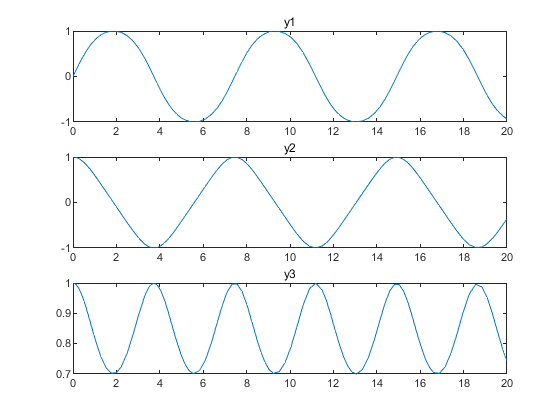

clear
y1diff = @(y2,y3) y2.*y3;
y2diff = @(y1,y3) -y1*y3;
y3diff = @(y1,y2) -0.51*y1.*y2;
sys = @(t,Y) [y1diff(Y(2),Y(3));y2diff(Y(1), Y(3));y3diff(Y(1),Y(2))];
y1_0 = 0; y2_0 = 1; y3_0 = 1;
[t, Y] = ode45(sys, [0 20], [y1_0 y2_0 y3_0]);
subplot(3,1,1); plot(t, Y(:,1));title('y1');
subplot(3,1,2); plot(t, Y(:,2));title('y2');
subplot(3,1,3); plot(t, Y(:,3));title('y3');

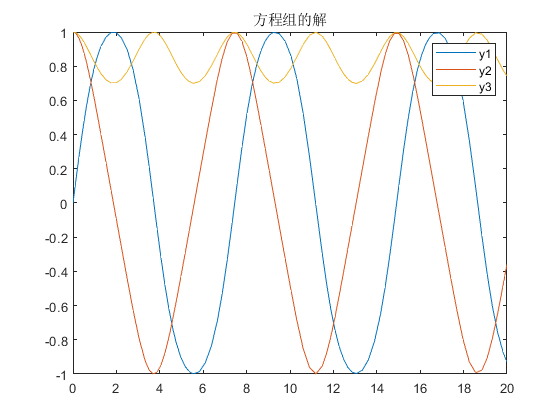

subplot(1,1,1); plot(t, Y);title('方程组的解');legend('y1', 'y2', 'y3');

## 实验11-4

clear
P1 = [0 1 0; 1 0 0; 0 0 1];
P2 = [1 0 0; 0 1 0; 1 0 1];
syms a b c d e f g h i
A  = [a b c; d e f; g h i];

### (1) $B=P_1 \cdot P_2 \cdot A$

B = P1 * P2 * A

$$B = \left(\begin{array}{ccc} d & e & f\\ a & b & c\\ a+g & b+h & c+i \end{array}\right)$$

### (2) 逆矩阵

invB = inv(B)

$$invB = \begin{array}{l} \left(\begin{array}{ccc} -\frac{b\,i-c\,h}{\sigma_{1}} & -\frac{b\,f-c\,e-e\,i+f\,h}{\sigma_{1}} & \frac{b\,f-c\,e}{\sigma_{1}}\\ \frac{a\,i-c\,g}{\sigma_{1}} & \frac{a\,f-c\,d-d\,i+f\,g}{\sigma_{1}} & -\frac{a\,f-c\,d}{\sigma_{1}}\\ -\frac{a\,h-b\,g}{\sigma_{1}} & -\frac{a\,e-b\,d-d\,h+e\,g}{\sigma_{1}} & \frac{a\,e-b\,d}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g \end{array}$$

验证结果，乘回去是单位阵：

simplify(B*invB)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

### (3) 下三角矩阵

tril(B)

$$ans = \left(\begin{array}{ccc} d & 0 & 0\\ a & b & 0\\ a+g & b+h & c+i \end{array}\right)$$

### (4) 行列式

det(B)

$$ans = a\,f\,h-a\,e\,i+b\,d\,i-b\,f\,g-c\,d\,h+c\,e\,g$$

## 实验11-5

### (1) 求极限

clear
syms x;
y = (x*(exp(sin(x))+1)-2*(exp(tan(x))-1))/((sin(x))^3)

$$y = \frac{x\,\left({\mathrm{e}}^{\sin\left(x\right)}+1\right)-2\,{\mathrm{e}}^{\tan\left(x\right)}+2}{{\sin\left(x\right)}^{3}}$$

limit(y, x, 0)

$$ans = -\frac{1}{2}$$

### (3) 求 y' 和 y''

y = (1 - cos(2*x))/x;
diff(y, x)

$$ans = \frac{2\,\sin\left(2\,x\right)}{x}+\frac{\cos\left(2\,x\right)-1}{x^{2}}$$

diff(y, x, 2)

$$ans = \frac{4\,\cos\left(2\,x\right)}{x}-\frac{4\,\sin\left(2\,x\right)}{x^{2}}-\frac{2\,\left(\cos\left(2\,x\right)-1\right)}{x^{3}}$$

### (5) 求 $\frac{\partial y}{\partial x}$、 ${\frac{\partial ^2 f}{\partial x \partial y} \bigg| }_{x=0,y=1}$

syms x y;
fxy = (x^2-2*x)*exp(-x^2-y^2-x*y);

$\frac{\partial y}{\partial x}$ 的解

diff(y,x)

$$ans = 0$$

${\frac{\partial ^2 f}{\partial x \partial y} $ 的符号解

dxy = diff(diff(fxy, x), y)

$$dxy = {\mathrm{e}}^{-x^{2}-x\,y-y^{2}}\,\left(2\,x-x^{2}\right)-{\mathrm{e}}^{-x^{2}-x\,y-y^{2}}\,\left(2\,x-2\right)\,\left(x+2\,y\right)-{\mathrm{e}}^{-x^{2}-x\,y-y^{2}}\,\left(2\,x-x^{2}\right)\,\left(x+2\,y\right)\,\left(2\,x+y\right)$$

${\frac{\partial ^2 f}{\partial x \partial y} \bigg| }_{x=0,y=1}$ 的数值解

x = 0; y = 1;
eval(dxy)

ans = 1.4715

## 实验11-6

clear
syms x


$$\int \frac{\rm dx}{ ( arcsin x)^2 \sqrt{1-x^2}}$$


int(1/((asin(x))^2*sqrt(1-x^2)))

$$ans = -\frac{1}{\mathrm{asin}\left(x\right)}$$


$$\int _0 ^{\rm ln 2} e^x ( 1+e^x)^2 \rm d x$$


eval(int(exp(x)*(1+exp(x))^2, 0, log(2)))

ans = 6.3333

## 实验12-4 

clear

### 书上的过时解法

syms x y


$$\frac{d^2y}{dx^2} + 4\frac{dy}{dx}+29y=0$$


eq = 'D2y + 4*Dy + 29*y';


$$y_1(0) = 0 , y_2(0) = 15$$


c1 = 'y(0)=0';
c2 = 'Dy(0)=15';

符号解为：

dsolve(eq, c1, c2, 'x')

$$ans = 3\,\sin\left(5\,x\right)\,{\mathrm{e}}^{-2\,x}$$

### matlab推荐解法

参考：[https://ww2.mathworks.cn/help/symbolic/dsolve.html](https://ww2.mathworks.cn/help/symbolic/dsolve.html)

syms y(x); Dy = diff(y); D2y = diff(y,2);
eq = D2y + 4 * Dy + 29 * y == 0

$$eq(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+4\,\frac{\partial }{\partial x}y\left(x\right)+29\,y\left(x\right)=0$$

c1 = y(0) == 0

$$c1 = y\left(0\right)=0$$

c2 = Dy(0) == 15

$$c2 = \left({\left(\frac{\partial }{\partial x}y\left(x\right)\right)|}_{x=0}\right)=15$$

ySol(x) = dsolve(eq, c1, c2)

$$ySol(x) = 3\,\sin\left(5\,x\right)\,{\mathrm{e}}^{-2\,x}$$

解析解绘图

fplot(ySol(x), [0 4]);
hold on

### 与数值解比较

原方程第一式为 $\frac{d^2y}{dx^2} + 4\frac{dy}{dx}+29y=0$

令 $y_{1} = y , y_{2} = y'$

则有


$$y'_1 = y_2$$


Dy1 = @(y2) y2;


$$y'_2 = -4y_2-29y_1$$


Dy2 = @(y1, y2) -4*y2-29*y1;
sys = @(x, Y) [Dy1(Y(2));Dy2(Y(1),Y(2))];

初值条件 $y_1(0) = 0 , y_2(0) = 15$

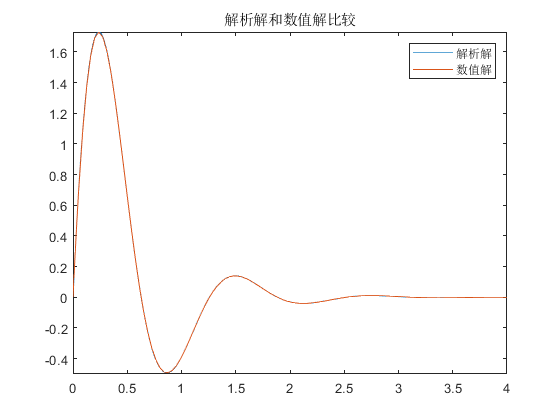

[t, yv] = ode45(sys, [0 4], [0 15]);
plot(t, yv(:,1));
title('解析解和数值解比较');
legend('解析解','数值解');
hold off